%Plot function to optimize code readability
function plotBandsBandPass(f_pass_low, f_pass_high,f_stop_low,f_stop_high, Rp, As)
    xline(f_pass_low/1000, 'r--', 'LineWidth', 1.3);   % cutoff
    xline(f_pass_high/1000, 'r--', 'LineWidth', 1.3);   % stopband edge
    xline(f_stop_low/1000, 'b--', 'LineWidth', 1.3);   % cutoff
    xline(f_stop_high/1000, 'b--', 'LineWidth', 1.3);   % stopband edge
    yline(-Rp, 'g--', 'LineWidth', 1.3);   % stopband edge
    yline(-As, 'v--', 'LineWidth', 1.3);   % stopband edge
    
    
    text(f_pass_low/1000, -5, ' f pass low', 'Color','red','FontSize',6);
    text(f_pass_high/1000, -5, ' f pass high', 'Color','red','FontSize',6);
    text(f_stop_low/1000, -18, ' f stop low', 'Color','blue','FontSize',6);
    text(f_stop_high/1000, -18, ' f stop high', 'Color','blue','FontSize',6);
end
function plotBands(f_pass, f_stop, Rp, As)
    xline(f_pass/1000, 'r--', 'LineWidth', 1.3);   % cutoff
    xline(f_stop/1000, 'b--', 'LineWidth', 1.3);   % stopband edge
    yline(-Rp, 'g--', 'LineWidth', 1.3);   % cutoff
    yline(-As, 'v--', 'LineWidth', 1.3);   % stopband edge
    text(f_pass/1000, -5, ' f_{pass}', 'Color','red','FontSize',8);
    text(f_stop/1000, -15, ' f_{stop}', 'Color','blue','FontSize',8);
    
end

## IIR_00 Pasabajos

% IIR_00 - Pasabajos

fs = 64000;% Frecuencia de muestreo
Rp = 3;% Ripple de banda de paso
As = 15;% Atenuacion en banda de rechazo

mayorOrden = 3;%Obtenido de mayorOrdenGG.m

%Frecuencias a utilizar

f_central =102.4;

f_stop = 512;

f_pass=  sqrt(f_central*f_stop);

Wp = [f_pass];
Ws = [f_stop];


% Normalizar para buttord
Wp = 2*pi*Wp;
Ws = 2*pi*Ws;




[n,Wn]=buttord(Wp, Ws, Rp, As,'s') 

n = 3

Wn = 1.8188e+03

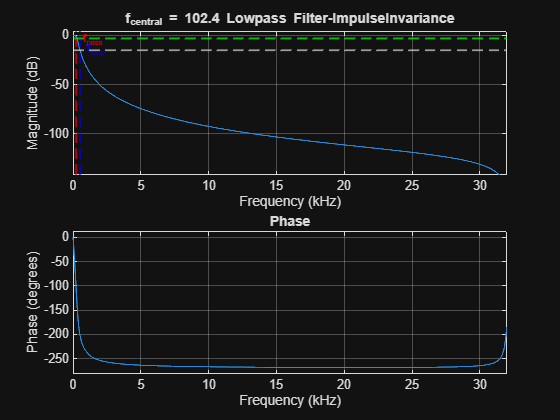

n = mayorOrden;%Asignación del mayor orden


[b,a] = butter(n,Wn,'low','s');
[bz_imp, az_imp] = impinvar(b,a,fs);
[bz_bi, az_bi] = bilinear(b,a,fs);

sos_imp = tf2sos(bz_imp,az_imp);
sos_bi = tf2sos(bz_bi, az_bi);

%=========================================
figure
freqz(sos_imp,2048,fs)
title(sprintf('f_{central} = %0.1f Lowpass Filter-ImpulseInvariance',f_central))


plotBands(f_pass, f_stop, Rp, As);

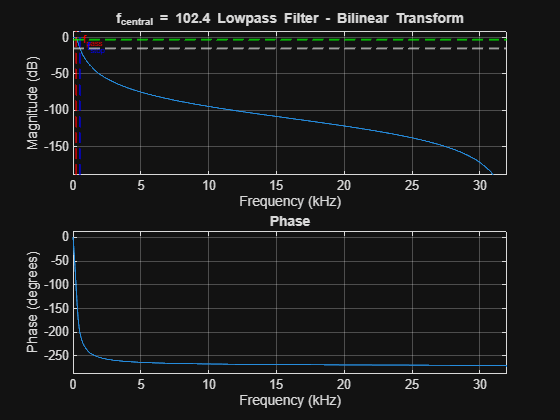


%===================================

figure
freqz(sos_bi,2048,fs)
title(sprintf('f_{central} = %0.1f Lowpass Filter - Bilinear Transform',f_central))
plotBands(f_pass, f_stop, Rp, As);

## IIR_01 - Pasabanda

% IIR_01 - Pasabanda


%Frecuencias a utilizar

f_central =512;%frecuencia c
f_stop_low = 102.4;
f_stop_high = 2560;

f_pass_low =  sqrt(f_central*f_stop_low);
f_pass_high =  sqrt(f_central*f_stop_high);

Wp = [f_pass_low   f_pass_high];
Ws = [f_stop_low   f_stop_high];



% Normalizar para buttord
Wp = 2*pi*Wp;
Ws = 2*pi*Ws;




[n,Wn]=buttord(Wp, Ws, Rp, As,'s')

n = 2

Wn = 1.0e+03 *

    1.3137    7.8779


n = mayorOrden;%Asignación del mayor orden


[b,a] = butter(n,Wn,'bandpass','s');
[bz_imp, az_imp] = impinvar(b,a,fs);
[bz_bi, az_bi] = bilinear(b,a,fs);

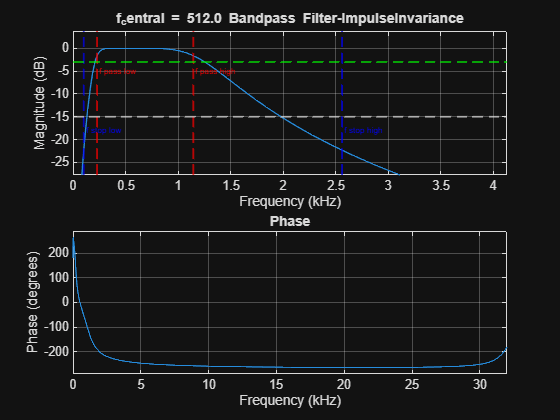


sos_imp = tf2sos(bz_imp,az_imp);
sos_bi = tf2sos(bz_bi, az_bi);

%=========================================
figure(1)
freqz(sos_imp,2048,fs)
title(sprintf('f_central = %0.1f Bandpass Filter-ImpulseInvariance',f_central))
plotBandsBandPass(f_pass_low, f_pass_high,f_stop_low,f_stop_high, Rp, As);

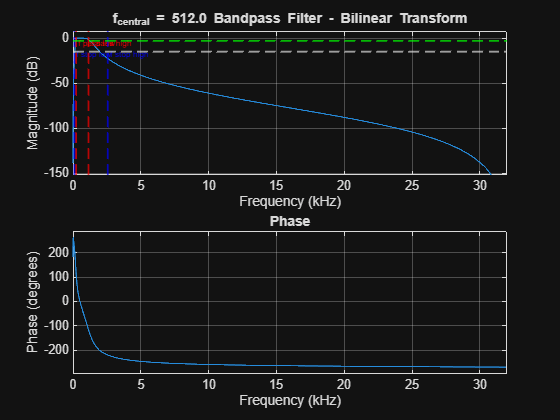


%===================================
figure(2)
freqz(sos_bi,2048,fs)
title(sprintf('f_{central} = %0.1f Bandpass Filter - Bilinear Transform',f_central))
plotBandsBandPass(f_pass_low, f_pass_high,f_stop_low,f_stop_high, Rp, As);

## IIR_02 Pasabanda

% IIR_02 - Pasabanda

%Frecuencias a utilizar

f_central =2560;%frecuencia c
f_stop_low = 512;
f_stop_high = 12800;

f_pass_low =  sqrt(f_central*f_stop_low);
f_pass_high =  sqrt(f_central*f_stop_high);

Wp = [f_pass_low   f_pass_high];
Ws = [f_stop_low   f_stop_high];



% Normalizar para buttord
Wp = 2*pi*Wp;
Ws = 2*pi*Ws;




[n,Wn]=buttord(Wp, Ws, Rp, As,'s')

n = 2

Wn = 1.0e+04 *

    0.6568    3.9389


n = mayorOrden;%Asignación del mayor orden


[b,a] = butter(n,Wn,'bandpass','s');
[bz_imp, az_imp] = impinvar(b,a,fs);
[bz_bi, az_bi] = bilinear(b,a,fs);

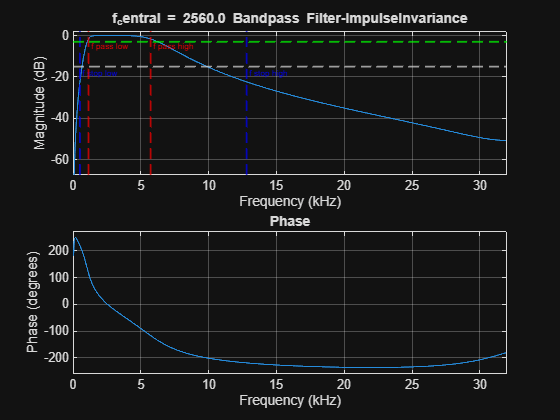


sos_imp = tf2sos(bz_imp,az_imp);
sos_bi = tf2sos(bz_bi, az_bi);

%=========================================
figure(1)
freqz(sos_imp,2048,fs)
title(sprintf('f_central = %0.1f Bandpass Filter-ImpulseInvariance',f_central))
plotBandsBandPass(f_pass_low, f_pass_high,f_stop_low,f_stop_high, Rp, As);

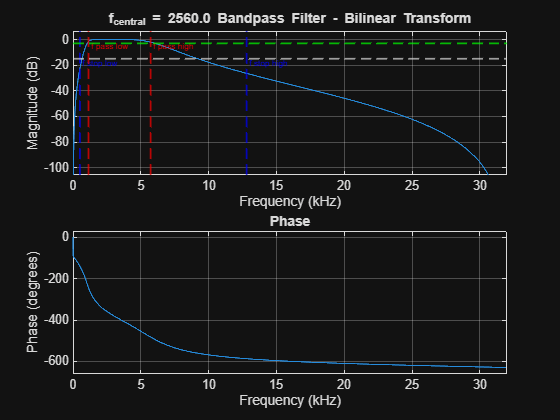


%===================================
figure(2)
freqz(sos_bi,2048,fs)
title(sprintf('f_{central} = %0.1f Bandpass Filter - Bilinear Transform',f_central))
plotBandsBandPass(f_pass_low, f_pass_high,f_stop_low,f_stop_high, Rp, As);

IIR_03 - Pasaaltos(impinvar requiere pasabanda)

% IIR_03 - {Pasaaltos


%Frecuencias a utilizar

f_central =12800;%frecuencia c
f_stop_low = 2560;
f_stop_high = 12800*4;
%f_stop_high = fs/2;


f_pass_low =  sqrt(f_central*f_stop_low);
f_pass_high =  sqrt(f_central*f_stop_high);

Wp = [f_pass_low   f_pass_high];
Ws = [f_stop_low   f_stop_high];



% Normalizar para buttord
Wp = 2*pi*Wp;
Ws = 2*pi*Ws;


%======= Pasaaltos con invariancia del impulso

[n,Wn]=buttord(Wp, Ws, Rp, As,'s')

n = 2

Wn = 1.0e+05 *

    0.3521    1.6432


n = mayorOrden;%Asignación del mayor orden


[b_bp,a_bp] = butter(n,Wn,'bandpass','s');
[bz_imp, az_imp] = impinvar(b_bp,a_bp,fs);


%====Pasaaltos para el bilinear

Wp_hp = 2*pi*f_pass_low;
Ws_hp = 2*pi*f_stop_low;

[n,Wn_hp]=buttord(Wp_hp, Ws_hp, Rp, As,'s');
n = mayorOrden;
[b_hp, a_hp] = butter(n,Wn_hp,'high','s');


[bz_bi, az_bi] = bilinear(b_hp,a_hp,fs);

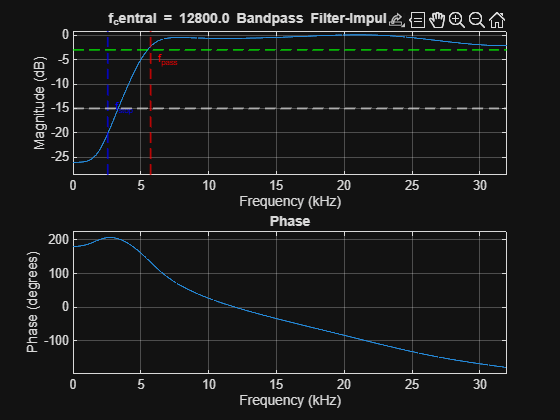


sos_imp = tf2sos(bz_imp,az_imp);
sos_bi = tf2sos(bz_bi, az_bi);

%=========================================
figure
freqz(sos_imp, 20000, fs)
title(sprintf('f_central = %0.1f Bandpass Filter-ImpulseInvariance',f_central))
plotBands(f_pass_low, f_stop_low, Rp, As);

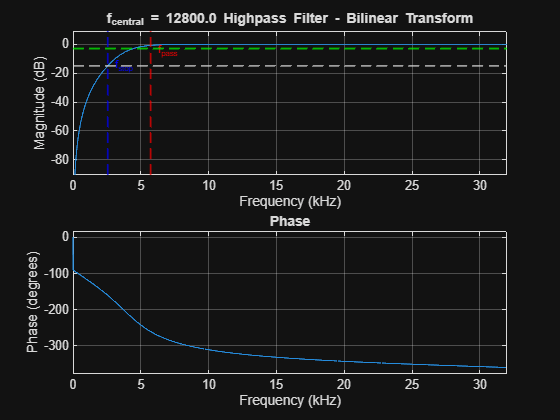


%===================================
figure
freqz(sos_bi,fs/2,fs)
title(sprintf('f_{central} = %0.1f Highpass Filter - Bilinear Transform',f_central))
plotBands(f_pass_low, f_stop_low, Rp, As);